# Question 2

Read input file:

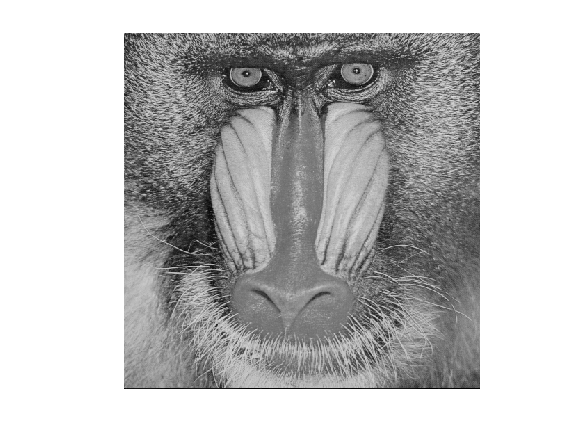

im = imread("/MATLAB Drive/images/mandrill.tif");
imshow(im)

## Floyd-Steinberg

Function as defined in the text book:

function y = fs(x,k)
    height = size(x,1);
    width = size(x,2);
    ed = [0 0 0 7 0;0 3 5 1 0;0 0 0 0 0]/16;
    y = uint8(zeros(height,width));
    z = zeros(height+4,width+4);
    z(3:height+2,3:width+2) = x;
    for i = 3:height+2,
        for j = 3:width+2,
            quant = floor(255/(k-1))*floor(z(i,j)*k/256);
            y(i-2,j-2) = quant;
            e = z(i,j)-quant;
            z(i:i+2,j-2:j+2) = z(i:i+2,j-2:j+2)+e*ed;
        end
    end
end

Dithering execution using k = 2 levels:

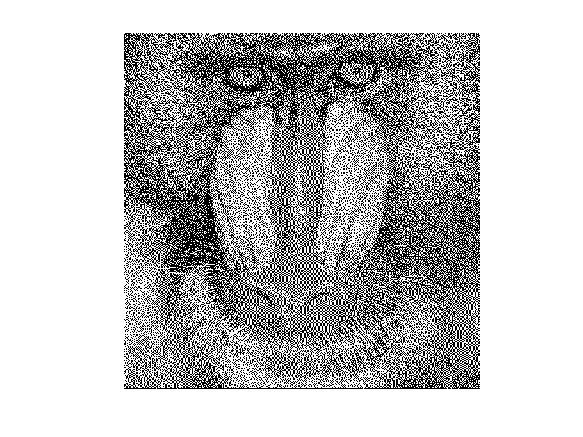

imfs = fs(im,2);
imshow(imfs)

## Jarvis-Judice-Ninke

Function as defined in the text book:

function out = jjn(im)
    height = size(im,1);
    width = size(im,2);
    out = zeros(size(im));
    ed = [0 0 0 7 5;3 5 7 5 3;1 3 5 3 1]/48;
    z = zeros(size(im)+4);
    z(3:height+2,3:width+2) = double(im);
    for i = 3:height+2,
        for j = 3:width+2,
            quant = 255*(z(i,j)>=128);
            out(i-2,j-2) = quant;
            e = z(i,j)-quant;
            z(i:i+2,j-2:j+2) = z(i:i+2,j-2:j+2)+e*ed;
        end
    end
    out = im2uint8(out);
end

Dithering execution at 2 levels:

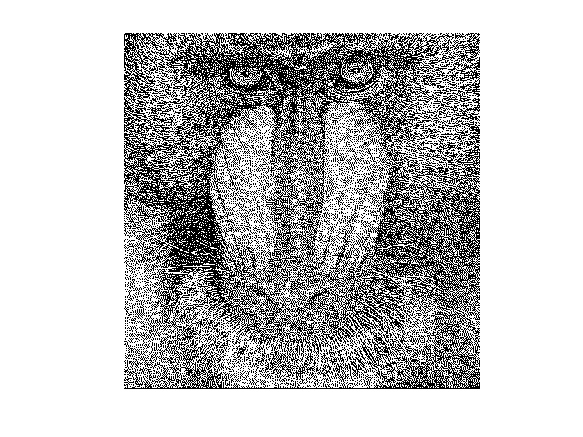

imjjn = jjn(im);
imshow(imjjn)

Both dithering executions result in a decent 2-level interpretation of the original grayscale image. I would say the quality is pretty similar, however, if we zoom in a little bit more:

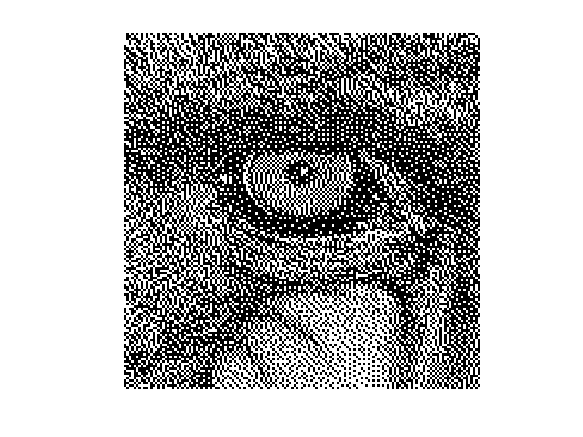

imfszoom = imfs(1:149,103:251);
imjjnzoom = imjjn(1:149,103:251);
imshow(imfszoom)

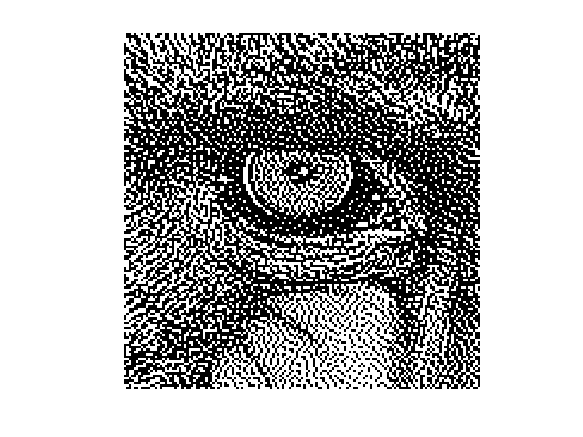

imshow(imjjnzoom)

We can see that the Jarvis-Judice-Ninke's distribution of black vs white pixels appears a little more "natural" and free-flowing, whereas the Floyd-Steinberg image has a lot more jagged lines. JJN's has a more complex method of including 12 pixels into the calculations instead of the 4 that FS uses, so that may be a contributing factor to JJN's higher-quality image. You can also see that the JJN image is a little more consistent with the coloring of certain areas. This is apparent when looking at the eye in the original image, where the JJN's all-white depiction of the whites of the eye is a little less noisy than the FS image. 

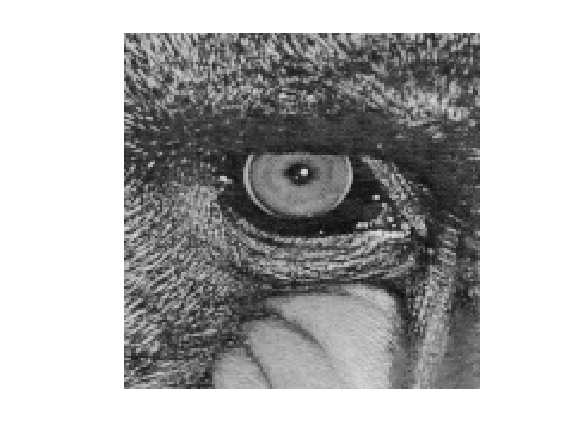

imzoom = im(1:149,103:251);
imshow(imzoom)